%% Parameters (golden car)
clc
clear
close all

m_s = 3000;  % Sprung mass (masa del chasis por rueda) (kg)
k_s = 63.3*m_s;  % Spring stiffness (rigidez del resorte) (N/m)
c_s = 6*m_s;  % Damping coefficient (coeficiente de amortiguamiento del amortiguador) (Ns/m)
k_t = 653*m_s;  % Tire stiffness (rigidez del neumático) (N/m)
c_t = 0;  % Tire damping (Ns/m)
m_u = 0.15*m_s;  % (masa de la rueda) Unsprung mass (kg)

% 
%% Diseño del PID
% x = [pos_u
%      pos_s
%      vel_u
%      vel_s]

M = [m_u 0
     0   m_s];
K = [k_s+k_t -k_s
     -k_s     k_s];
C = [c_s+c_t -c_s
     -c_s     c_s];
A_ss = [ 0 0 1 0 
         0 0 0 1
        -M\K -M\C]; 

B_ss = [ 0
         0
         (M^-1) * [ -1
                    1 ]];
Bd_ss = [ 0
          0
          0
          1/m_s];

C_ss = [ 1 -1 0 0]; % Esto en sí mide la compresión. Osea, es positiva cuando esta comprimido.
D_ss = [ 0 ];
H  = ss(A_ss, B_ss, C_ss, D_ss);
Hd = ss(A_ss, Bd_ss, C_ss, D_ss);

%% Ejercicio 1. 
% Construya un modelo en simulink usando simscape (mecánica 
% traslacional) de la suspensión de un cuarto de vehículo (un colectivo).
% Los parámetros se dan arriba.
% Las perturbaciones del terreno aparecen a los 50 segundos y se modelan 
% como un ruido de 1 m/s^2 RMS (el bloque Band-Limited White Noise ya está configurado)
% SI EL MODELO ES CORRECTO, generan compresiones de la suspensión 
% de 3 a 4 cm pico.
% (2 puntos)

# Chequeo del modelo

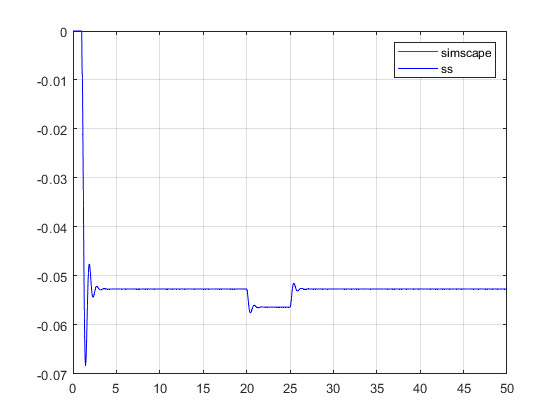

x0             = [0;0;0;0];
out            = sim('ModelVerification.slx');
t              = out.compresion.time;
compresion     = out.compresion.signals.values;

t_ss           = out.compresion_ss.time;
compresion_ss  = out.compresion_ss.signals.values;

t_est_ss           = out.estado_ss.time;
estado_ss          = out.estado_ss.signals.values;

t_est_sims           = out.estado_sims.time;
estado_sims          = out.estado_sims.signals.values;


plot(t, compresion, '-r'); grid on;hold on;
plot(t_ss, compresion_ss, '-b');hold off;
legend('simscape', 'ss');

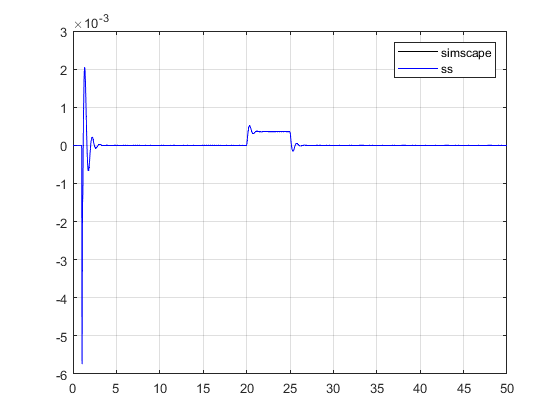

figure;

plot(t_est_sims, estado_sims(:,1), '-k');grid on;hold on;
plot(t_est_ss, estado_ss(:,1), '-b');hold off;
legend('simscape', 'ss');

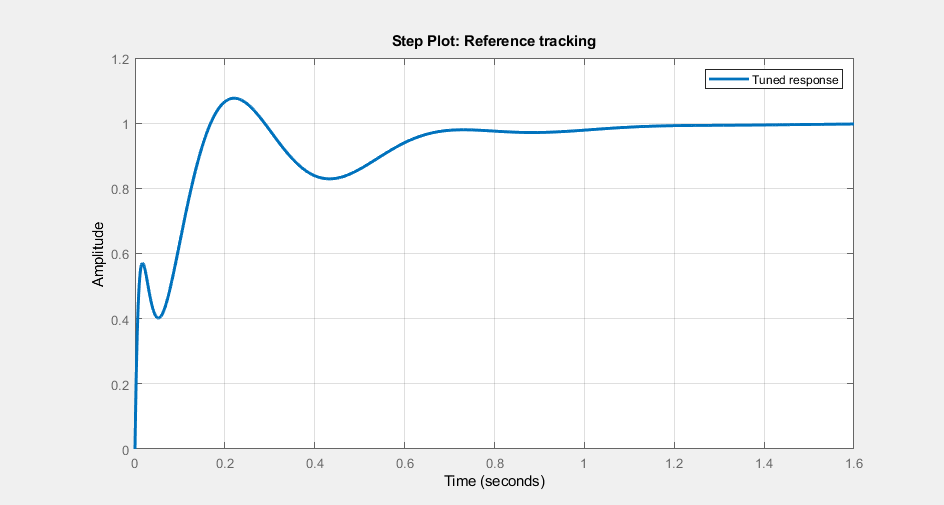

%% Ejercicio 2. 
% Considerando un sensor ideal de distancia para medir la compresión de
% la suspensión:
% Implemente un PID para que el colectivo descienda y permita el ingreso 
% de pasajeros. 
% Este controlador, cuando el chofer da un escalón a la referencia
% de -10 cm a los 10 s, debe hacer que la suspensión se comprima 10 cm, 
% sin error en estado estacionario, sin sobre-impulso y con un tiempo de 
% establecimiento de menos de 1.0 s.
% Por otra parte, cuando sube el pasajero, modelado como perturbación
% tipo escalón de 700 N a los 20 s, el controlador debe rechazar la 
% perturbación con un tiempo de establecimiento de menos de 1.0 s.
% Un pasajero baja a los 25 s, lo cual también se modela con un escalón.
% Para esto puede usar el comando
pidTuner(H, 'PID');

% y obtener las ganancias por tanteo observando la tabla mostrada al pulsar 
% el botón Show Parameters.
% (2 puntos)

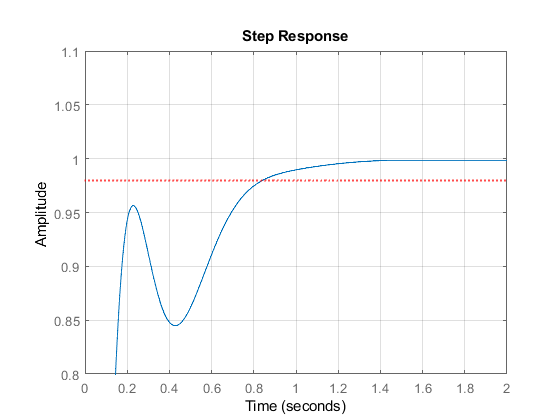

kp  = controler.Kp*0.6;
ki  = controler.Ki*0.8;
kd  = controler.kd*1;
H   = tf(H);
Gc  = tf([kd kp ki], [1 0]);
Gcl = H*Gc/(1 + H*Gc);

step(Gcl); grid on; xlim([0 2]);ylim([0.8 1.1]); hold on;yline(0.98,'r:','LineWidth',1.5);hold off;

stepinfo(Gcl)

ans = struct with fields:
        RiseTime: 0.1737
    SettlingTime: 0.8426
     SettlingMin: 0.8449
     SettlingMax: 0.9984
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9984
        PeakTime: 1.4278


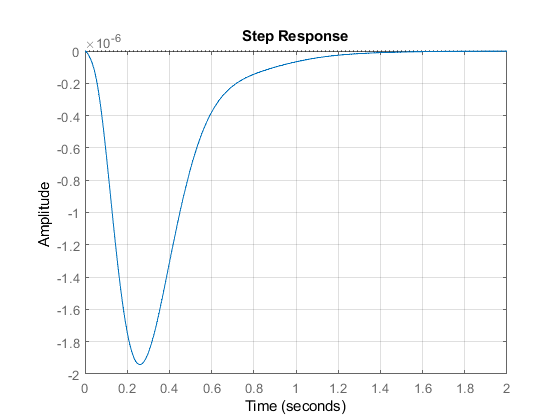

Hd   = tf(Hd);
Gcld = Hd/(1 + H*Gc);
step(Gcld); grid on; xlim([0 2]);

stepinfo(Gcld)

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 1.1177
     SettlingMin: -1.9415e-06
     SettlingMax: -2.0307e-10
       Overshoot: Inf
      Undershoot: Inf
            Peak: 1.9415e-06
        PeakTime: 0.2612


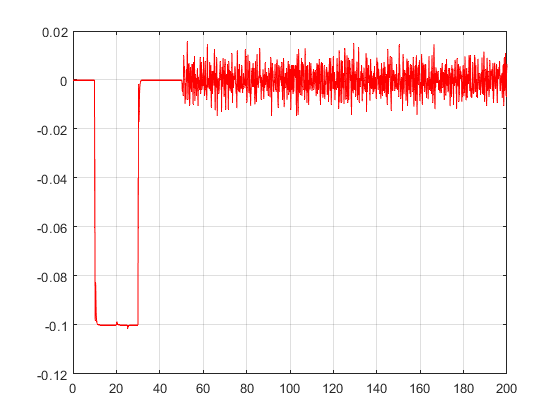

out = sim('E2.slx');
t          = out.compresion.time;
compresion = out.compresion.signals.values;
plot(t, compresion, '-r'); grid on;

%% Ejercicio 3
% Modifique el controlador de manera que la acción de control nunca 
% supere los 20000 N en valor absoluto. Se permite degradación del
% desempeño ante el escalón en la referencia, pero ante el escalón de la
% perturbación debe mantener la dinámica.
% (2 puntos)

%% Ejercicio 4
% Agregue al modelo de simulink los componentes necesarios para modelar los
% siguientes detalles:
% La compresión de la suspensión se mide con tres sensores de distancia que
% tienen los siguientes ruidos (no correlacionados):
% Sensor A: 10 mm RMS (el bloque Band-Limited White Noise ya está configurado)
% Sensor B: 5 mm RMS (el bloque Band-Limited White Noise ya está configurado)
% Sensor C: 5 mm RMS (el bloque Band-Limited White Noise ya está configurado)
% (1 punto)

%% Ejercicio 5
% Diseñe e implemente un observador de estado (posiblemente como filtro de 
% Kalman) de manera de tener una estimación de la altura del chasis con un
% ruido RMS menor a 5 mm.
% (2 puntos) Si lo diseña por ubicación de polos (usando place o aker)
% (3 puntos) Si lo diseña como filtro de Kalman-Bucy de tiempo continuo 
% (usando lqr), puede llegar a un ruido de 3.5 mm RMS en la primer intento
% correcto

# LQR

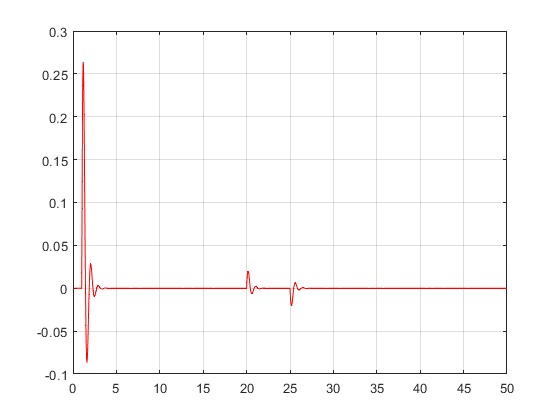

Aaug     = [A_ss zeros(4, 1); C_ss, 0];

Baug     = [B_ss; 0];
C_ss_aux = [C_ss; 0 0 1 -1];
Caug     = [C_ss_aux   zeros(2,1)
            0    0    0    0    1];
    
comp_typ     = 0.1* 4.88; % compresión típica [m]
comp_dot_typ = 0.1* 0.83; % velocidad de compresión típica [m/s]
u_typ        = 1e4* 0.34; % acción de control típica [N]
err_int_typ  = 1*   10; % integral del error tipica [m*s]

%Qy          = 1/comp_typ^2;
Qy_aug      = [1/comp_typ^2        0                 0
                0           1/comp_dot_typ^2         0
                0                  0         1/err_int_typ^2];
%Qx          = C_ss'*Qy*C_ss;
Qxaug       = Caug'*Qy_aug*Caug;
Qu          = 1/u_typ^2;
Kaug        = lqr(Aaug, Baug, Qxaug, Qu);
%K           = lqr(A_ss, B_ss, Qx, Qu)
ki          = Kaug(end)
K           = Kaug(1:end-1);
kr          = 1/(C_ss*(-(A_ss-B_ss*K)\B_ss))
out  = sim('LQR.slx');

ki = -340.0000

t          = out.compresion.time;
compresion = out.compresion.signals.values;

kr = -1.9011e+05

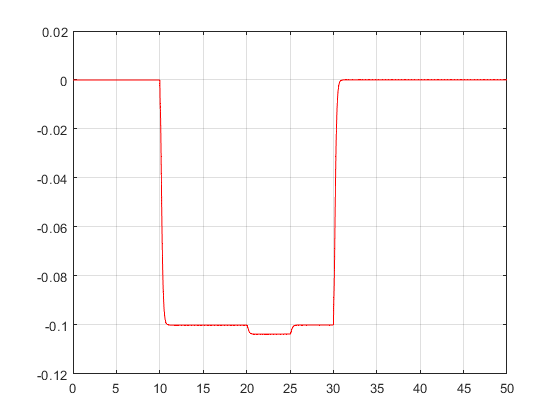

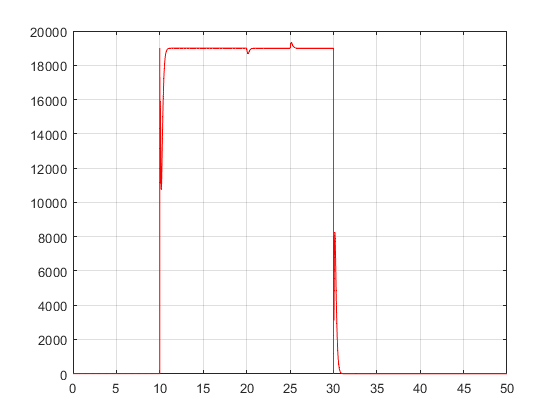

t_u        = out.ControlSignal.time;
u          = out.ControlSignal.signals.values;

plot(t, compresion, '-r'); grid on;
plot(t_u, u, '-r'); grid on;